%EE451 Homework 7
% Lisa Jacklin
% 11/1/2023

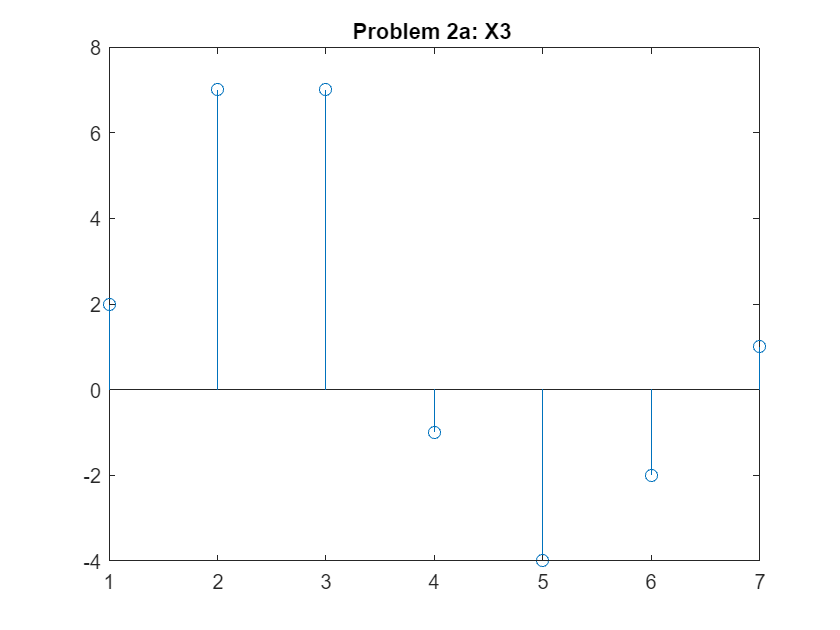


%Problem 2
%part a: convolution of x1n and x2n
x1n = [1 3 2 -1];
x2n = [2 1 0 -1];

X3 = conv(x1n, x2n);
%now that X3 has been determined we need to plot it!
stem(X3);
title("Problem 2a: X3 ");

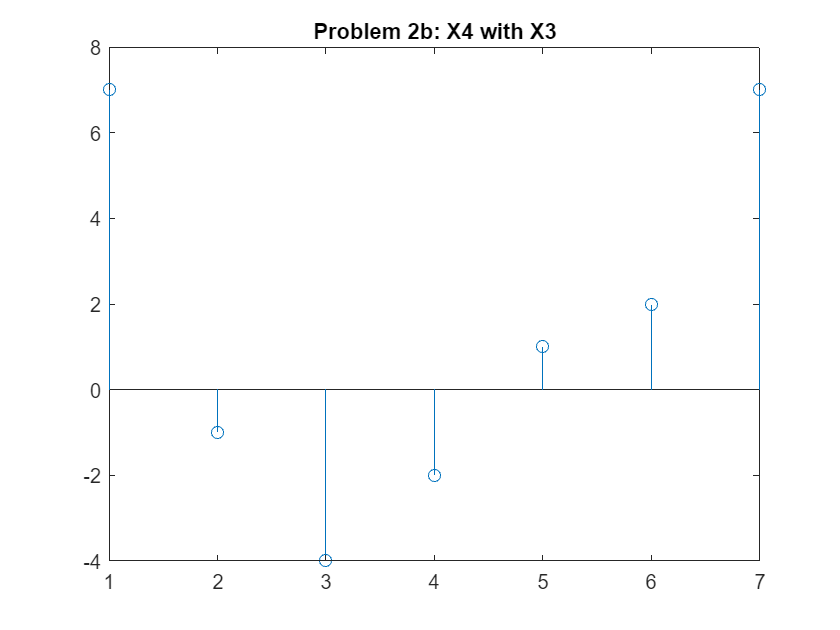


%part b: circular convolution of 5 of x1n and x2n
%this has to be determined using only x3 to sketch and determine the
%circular convolution....

%we are given that the circular shift is 5 so
X4 = circshift(X3,5);

%now we can graph this
stem(X4);
title("Problem 2b: X4 with X3");

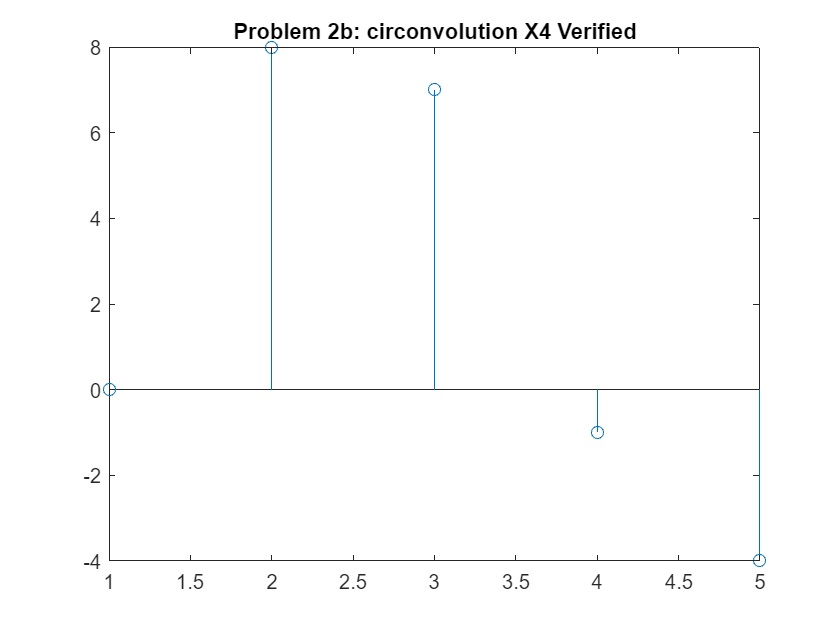


%to double check that this is correct, I will use the function
%circconvolution created in class which takes two signals, x1 and x2 as well
%as the shift to compare and verify that X4 above is correct.

X4b = circconvolution(x1n, x2n, 5);
stem(X4b);
title("Problem 2b: circonvolution X4 Verified");


%note that although X4b only displays 5 samples, these are the same
%signals.


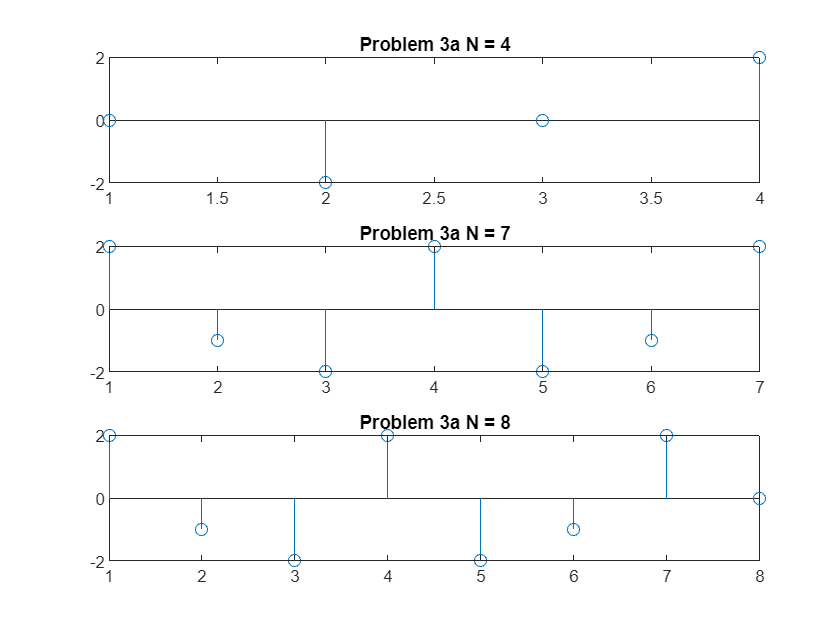

%Problem 3
%given the following sequences of x1n and x2n, do the following....

x1n4 = [2 1 1 2];
x2n4 = [1 -1 -1 1];

%part a: compute and plot the circular conv. x1n4(N)x2n4 for N = 4, N = 7,
%and N = 8.

%for N = 4
Xa1 = circconvolution(x1n4, x2n4, 4); 
subplot(3, 1, 1);
stem(Xa1);
title("Problem 3a N = 4")

%for N = 7
Xa2 = circconvolution(x1n4, x2n4, 7);
subplot(3,1, 2);
stem(Xa2);
title("Problem 3a N = 7");

% for N = 8
Xa3 = circconvolution(x1n4, x2n4, 8);
subplot(3,1,3);
stem(Xa3);
title("Problem 3a N = 8");

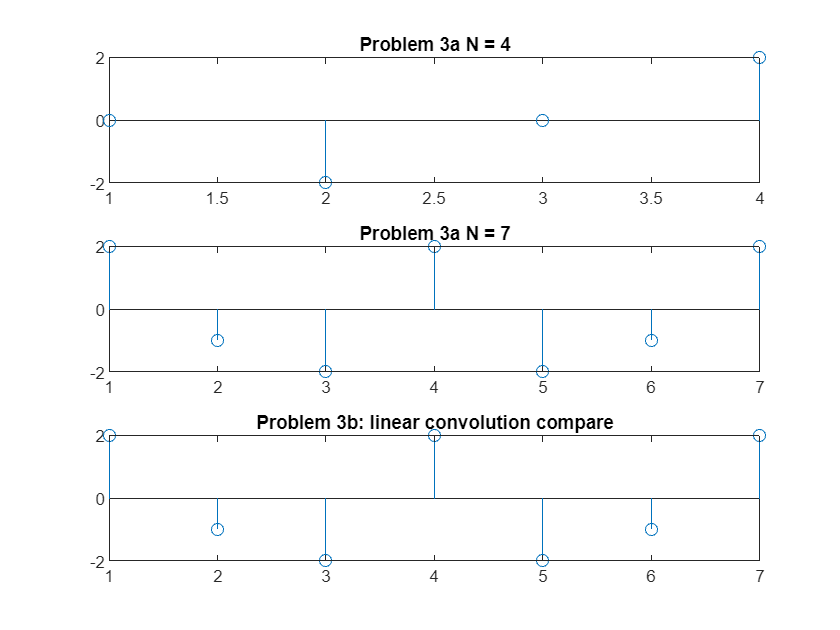


%Part b: compute and plot the linear convolution x1n * x2n

X3b = conv(x1n4, x2n4);
stem(X3b);%this plot is displayed in place of N = 8, look at how it compares to N = 7
title("Problem 3b: linear convolution compare");

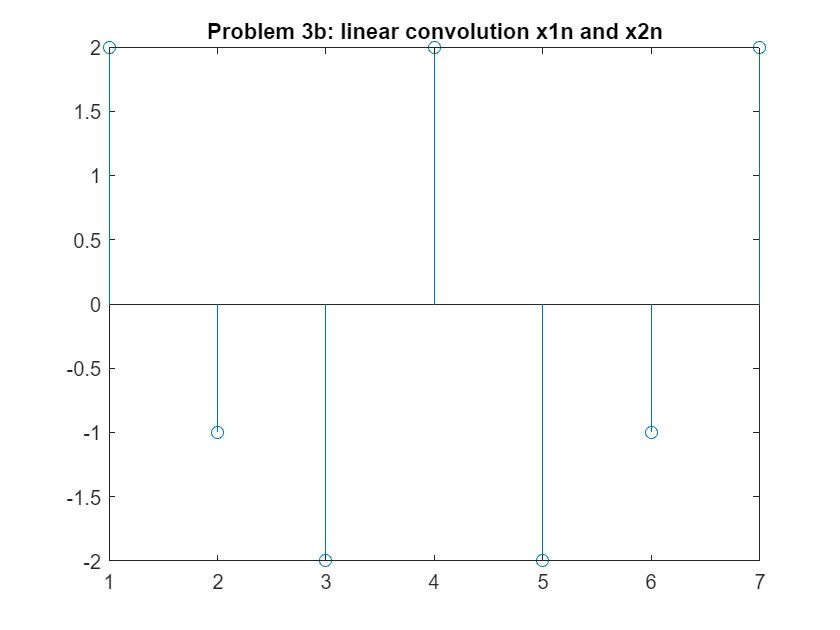

figure; stem(X3b); %and for clarity, how it appears on its own.
title("Problem 3b: linear convolution x1n and x2n");

%Problem 4
%first, I need to generate xn which is a random uniformly distributed
%function that runs between [-1 1] for 0 <=n<= 10^7 (or 10^6 or higher
%depending on processor...Will note on this as I continue through
%programming)

% Define the number of samples. Note that for quick compilations, I am
% sticking with N = 10^7, but my desktop can run up to 10^9 and laptop up
% to 10^12 although with a very unhappy matlab...
N = 10^7;
% Generate random numbers in the range [0, 1] since rand does not generate
% negative numbers.
random_numbers = rand(N, 1);
% Scale to the range [-1, 1] so we can achieve what we are looking for!
x4n = 2 * random_numbers - 1;
% Now, x4n contains N random values in the range [-1, 1].

%now we need to include hn
n = 0:1:100;
hn = sin(0.4*4*pi*n);

%now, setting up to take 5 samples for each of the parts of problem 4 and
%averaging.

%part a: matlab conv function between x and h
%part a1:
Reps = 5; %5 samples

tic;%starts the timer
    for i = 1:Reps
        tstart = tic; %sets tstart as the timer value
        
        X4a = conv(x4n, hn); %convolution being tested

       telapsed = toc(tstart); %end the timer and calculate the time
       disp("Time Results:" + telapsed+ " sec"); %display each of the 5 tests
    end

Time Results:0.026016 sec
Time Results:0.0226 sec
Time Results:0.020896 sec
Time Results:0.020733 sec
Time Results:0.02102 sec



    averageTimeA = toc/Reps;
    disp("Average Time of 5 generations: " + averageTimeA + " sec");

Average Time of 5 generations: 0.024232 sec



    %part a2: overlap and save (developed in lab...) along with FFT of block
    %size 1024.

    N4b = 1024; %the given block size
    %note that Reps is the same for all of problem 4
    tic;%starts the timer
    for i = 1:Reps
        tstartb = tic; %sets tstart as the timer value
        %need to check overlap and save for accuracy
        X4b = overlapsave(hn, x4n, N4b); %overlap and save being tested

       telapsedb = toc(tstartb); %end the timer and calculate the time
       disp("Time Results:" + telapsedb+ " sec"); %display each of the 5 tests
    end

Time Results:0.085839 sec
Time Results:0.031132 sec
Time Results:0.031811 sec
Time Results:0.037228 sec
Time Results:0.028781 sec



    averageTimeA = toc/Reps;
    disp("Average Time of 5 generations: " + averageTimeA + " sec");

Average Time of 5 generations: 0.046322 sec




     %part a3: overlap and save (developed in lab...) along with FFT of block
    %size 4096.

    N4c = 4096; %the given block size

    %note that Reps is the same for all of problem 4
    tic;%starts the timer
    for i = 1:Reps
        tstartc = tic; %sets tstart as the timer value
        
        X4c = overlapsave(hn, x4n, N4c); %overlap and save being tested

       telapsedc = toc(tstartc); %end the timer and calculate the time
       disp("Time Results:" + telapsedc+ " sec"); %display each of the 5 tests
    end

Time Results:0.026984 sec
Time Results:0.02704 sec
Time Results:0.028541 sec
Time Results:0.026032 sec
Time Results:0.029344 sec



    averageTimeA = toc/Reps;
    disp("Average Time of 5 generations: " + averageTimeA + " sec");

Average Time of 5 generations: 0.029583 sec



%Problem 4 part b: using N/2 logbase 2 N as the number of complex
%multiplications of one FFt, estimate the total number of
%multiplications for each case in subitem I above.

%First, considering convolution of part a1, since linear or direct
%convolution is used over a length of N, and we know that convolution
%essentially takes then legnth of both and multiplies them, assuming that N
%is the length of both signals, and noting that linear convolution which is
%done above, is not circular so the complex formula does not apply, thus
% N*N is the estimated total of multiplications required.

%Considering overlap save in Part a2 where N = 1024. Since overlap and save
%is a more efficient version of linear convolution, due to its ability
%to break down normal convolution into manageable part, the complex
%multiplication equation can be used to give an estimate: 1024/2 + logbase2
%of 1024 so 510 + 10 or an estimated 520 multiplications.

%For parta3, with N = 4096, we can do just like we did for part a2, using
%the complex multiplication equation to calcuation an estimation: 4096/2 +
%logbase2 of 4096 = 2048 + 12 = 2060 estimated multiplications.

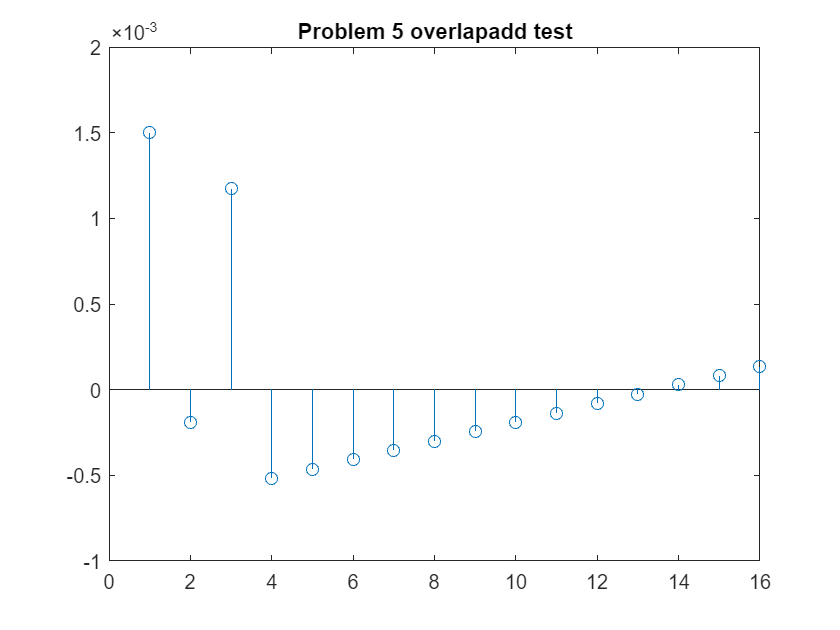

%problem 5: checking part a
%note thatoverlapadd.m is attached and commented out at the very end of
%this mlx script.

%to check that my overlapadd.m is created properly, I am given some values
N5 = 16; %samplings
n = 0:1:4000;
x5n = cos(pi*n/500); h5n = [1 -1 1 -1];

%with the items given above, I will run them through overlapadd as well as
%overlapsave which was developed in lab.
y = overlapadd(x5n, h5n, N5);
stem(y);
title("Problem 5 overlapadd test");

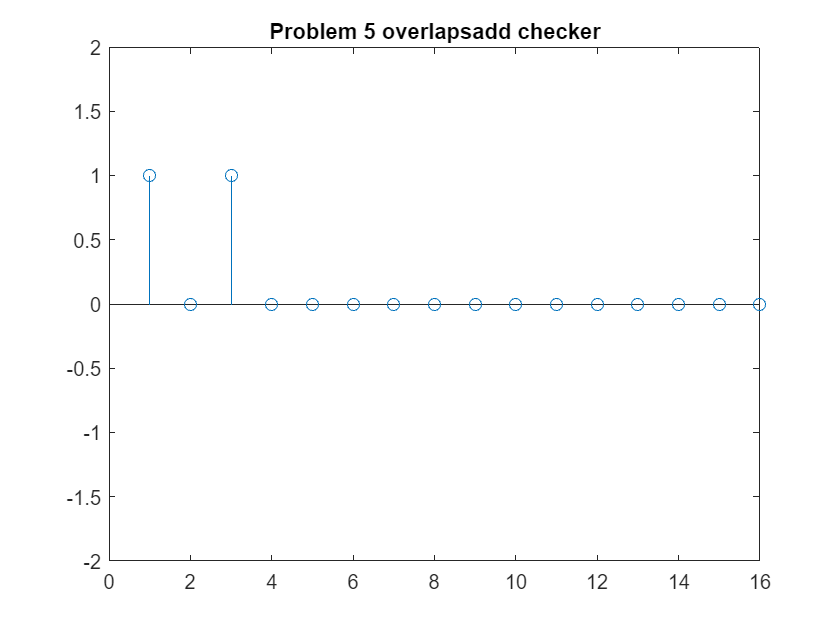

%now to double check by using overlap save developed in class:
y2 = overlapsave(x5n, h5n, N5);
stem(y2); axis([0 16 -2 2]);
title("Problem 5 overlapsadd checker");

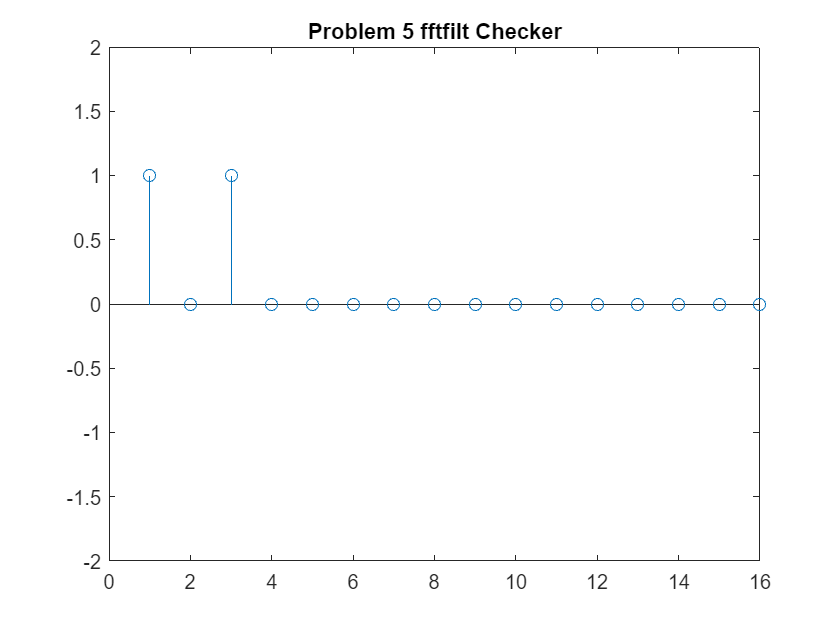


y5n = fftfilt(h5n, x5n, N5);
stem(y5n);axis([0 16 -2 2]);
title("Problem 5 fftfilt Checker");


%overlapadd.m:

% function [y] = overlapadd(x, h, N)
% % [y] = overlapadd(x, h, N)
% % y = output sequence
% % x = input sequence
% % h = impulse sequence
% % N = block length (requires to be power of 2)
% 
% N = 2^(ceil(log2(N)));  % Use log2 to find the nearest power of 2.
% Lenx = length(x);
% M = length(h);
% M1 = M - 1;
% L = N - M1;
% h = fft(h, N);
% 
% x = [x, zeros(1, M1), zeros(1, N-1)];
% K = floor(Lenx / L);  % Changed calculation for K.
% Y = zeros(K, N);  % Changed size to avoid extra zeros.
% for k = 0:K-1  % Adjusted loop to not process extra block.
%     xk = fft(x(k*L+1:k*L+N));
%     Y(k+1, :) = ifft(xk .* h);
% end
% y = sum(Y, 1);  % Sum the rows to obtain the output sequence.
% end
